close all
clear all
clc

## Función de transferencia del sistema original en lazo abierto

G = tf([0 0 0 4.9383],[1 3.6415 3.57 4.9383])

G =
 
               4.938
  --------------------------------
  s^3 + 3.642 s^2 + 3.57 s + 4.938
 
Continuous-time transfer function.



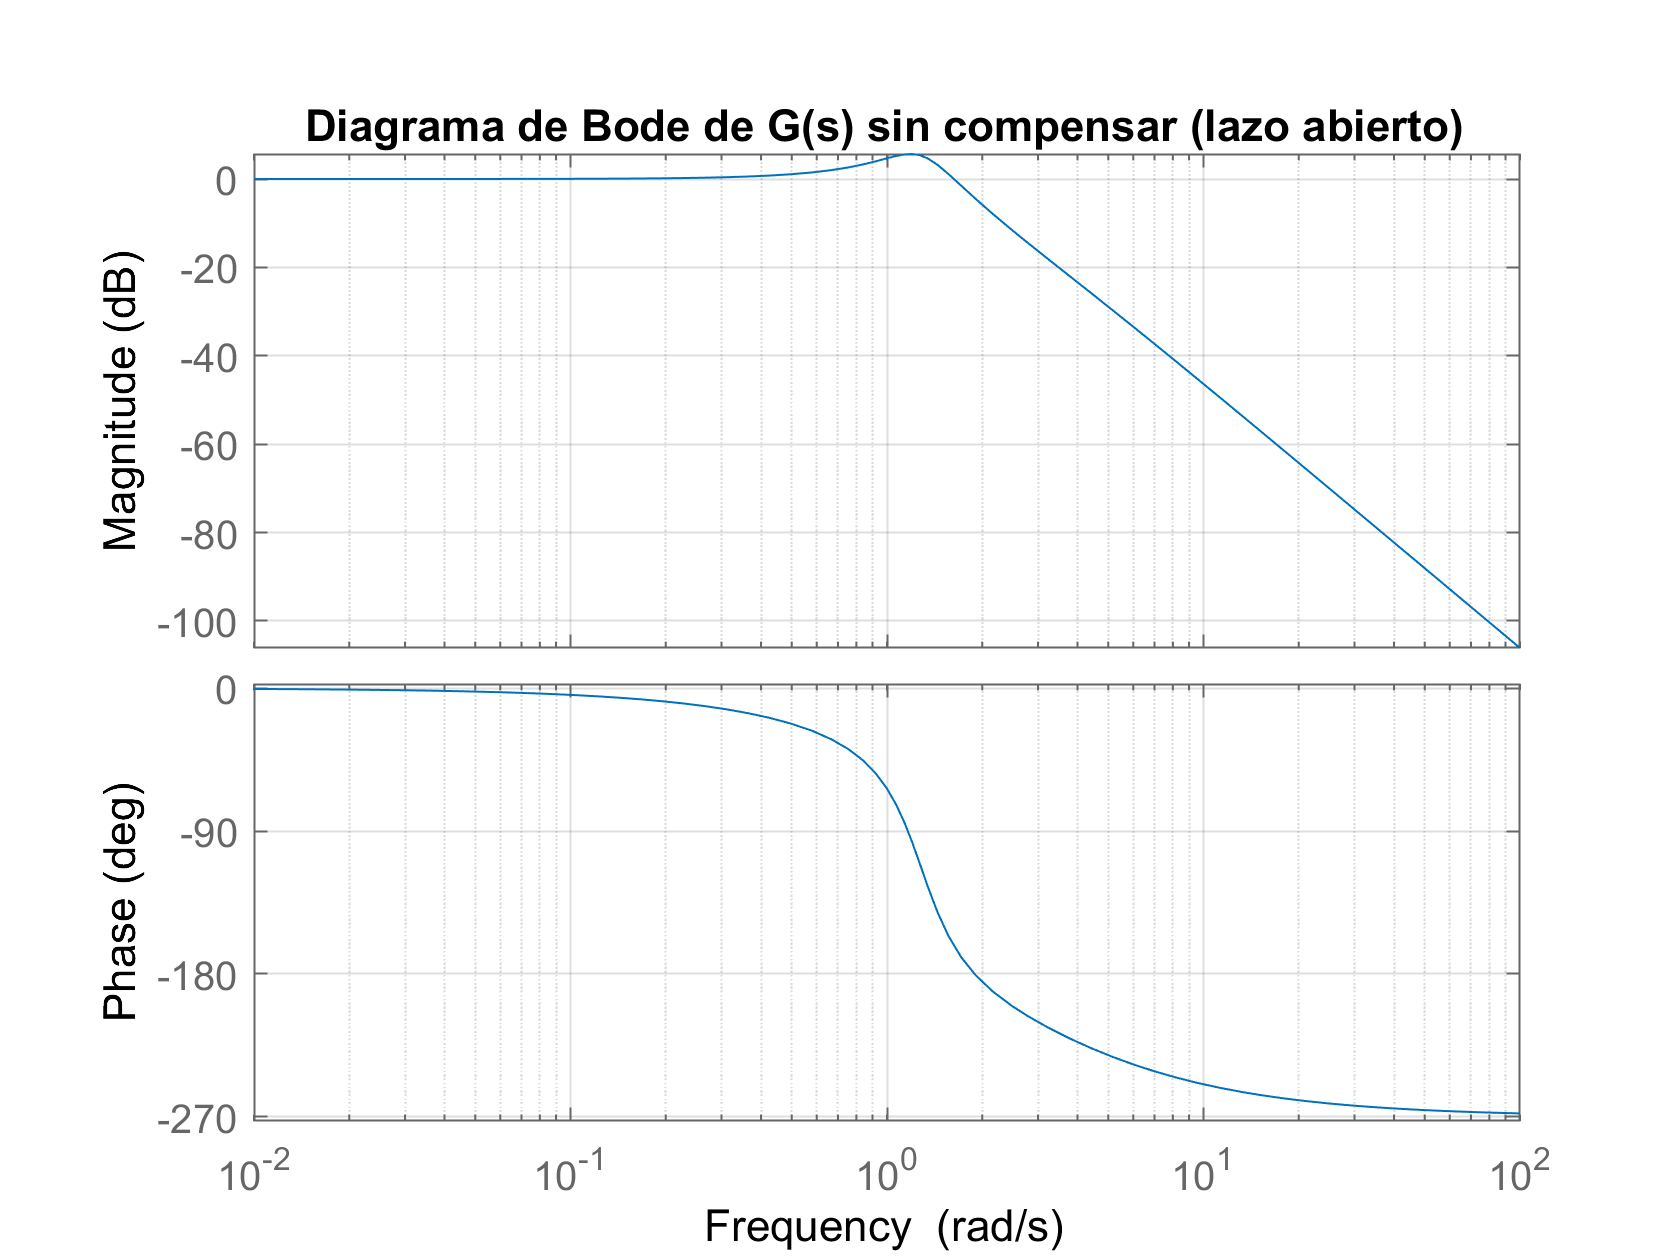

bode(G,{0.01 100})
title('Diagrama de Bode de G(s) sin compensar (lazo abierto)')
grid

## Función de transferencia del controlador de adelanto

kc = 30.3;
pc = -13.4165;
zc = -0.4428;
C=zpk(zc, pc, kc)

C =
 
  30.3 (s+0.4428)
  ---------------
     (s+13.42)
 
Continuous-time zero/pole/gain model.



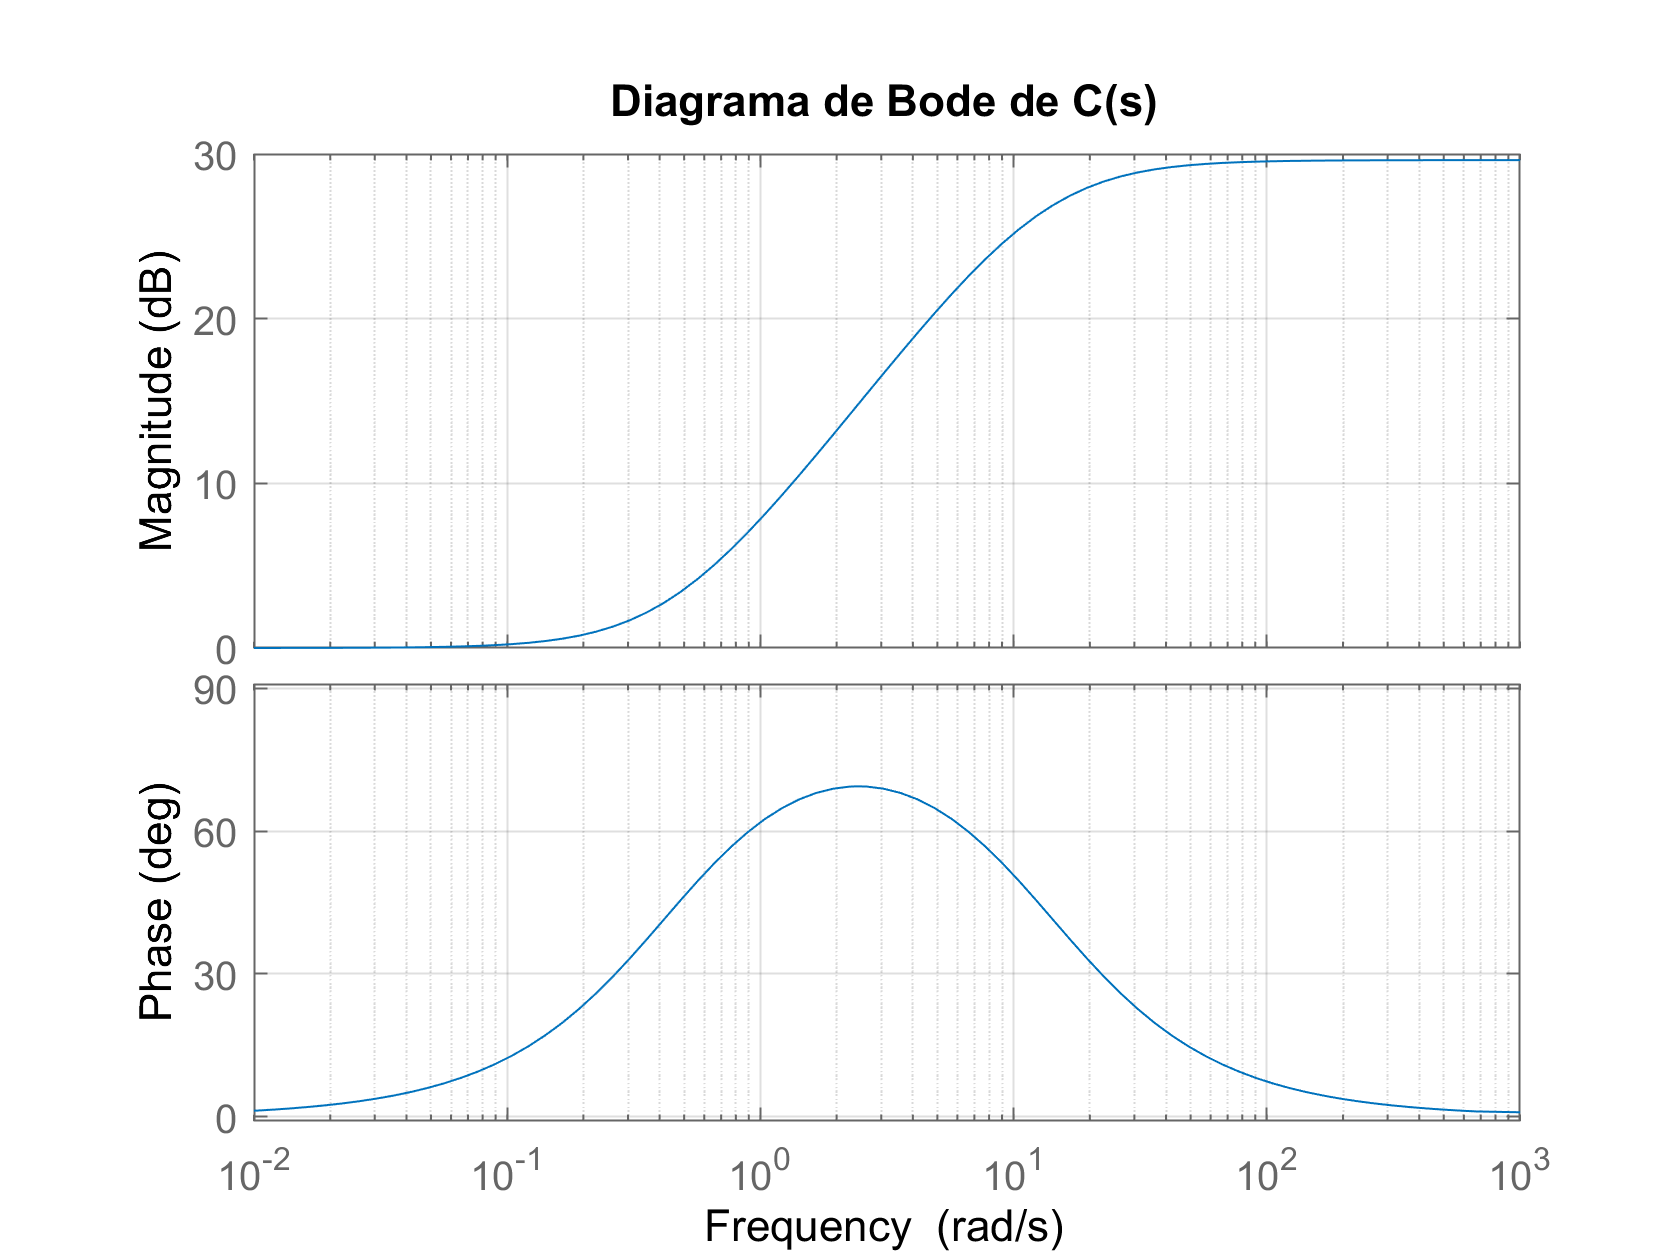

bode(C)
title('Diagrama de Bode de C(s)')
grid

## Función de transferencia del sistema + controlador de adelanto

sysC=G*C

sysC =
 
             149.63 (s+0.4428)
  ---------------------------------------
  (s+3) (s+13.42) (s^2 + 0.6413s + 1.646)
 
Continuous-time zero/pole/gain model.



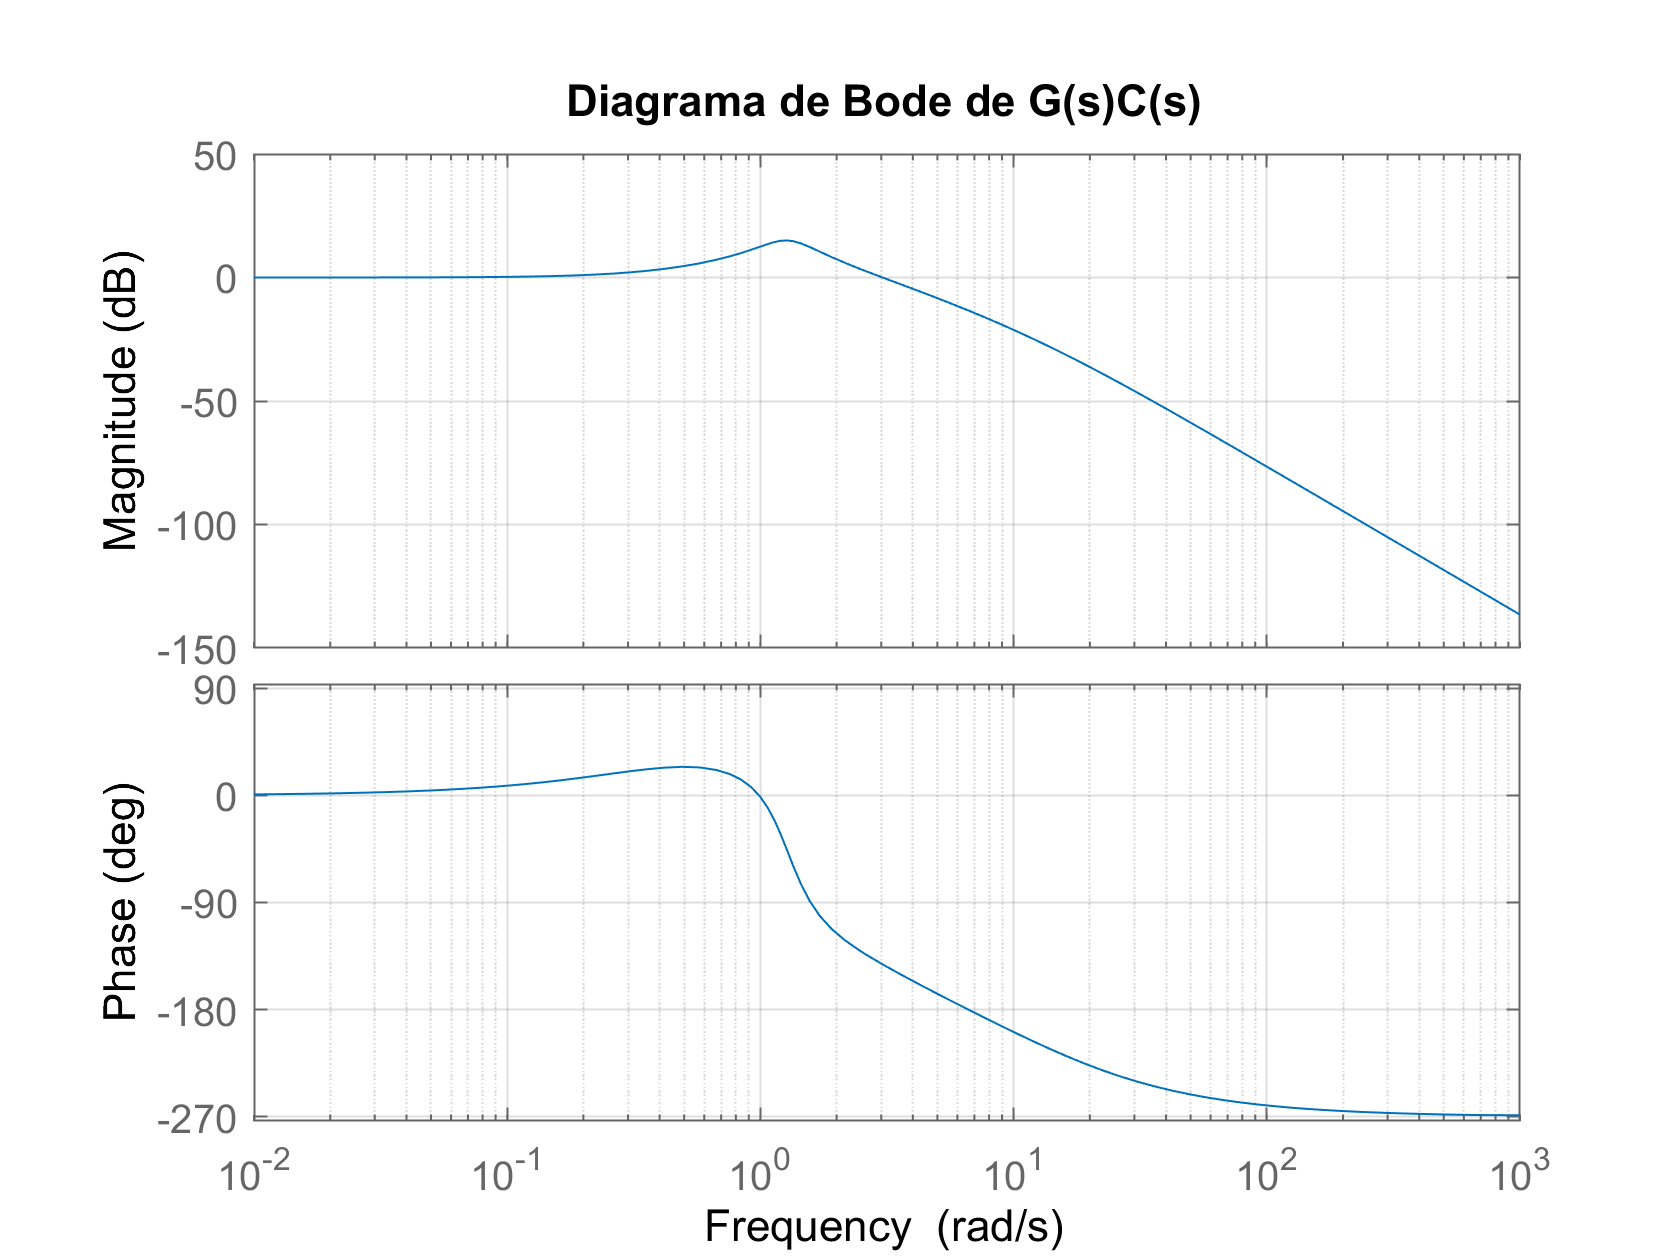

bode(sysC)
title('Diagrama de Bode de G(s)C(s)')
grid

## Comparación entre el sistema sin compensador y el sistema compensado

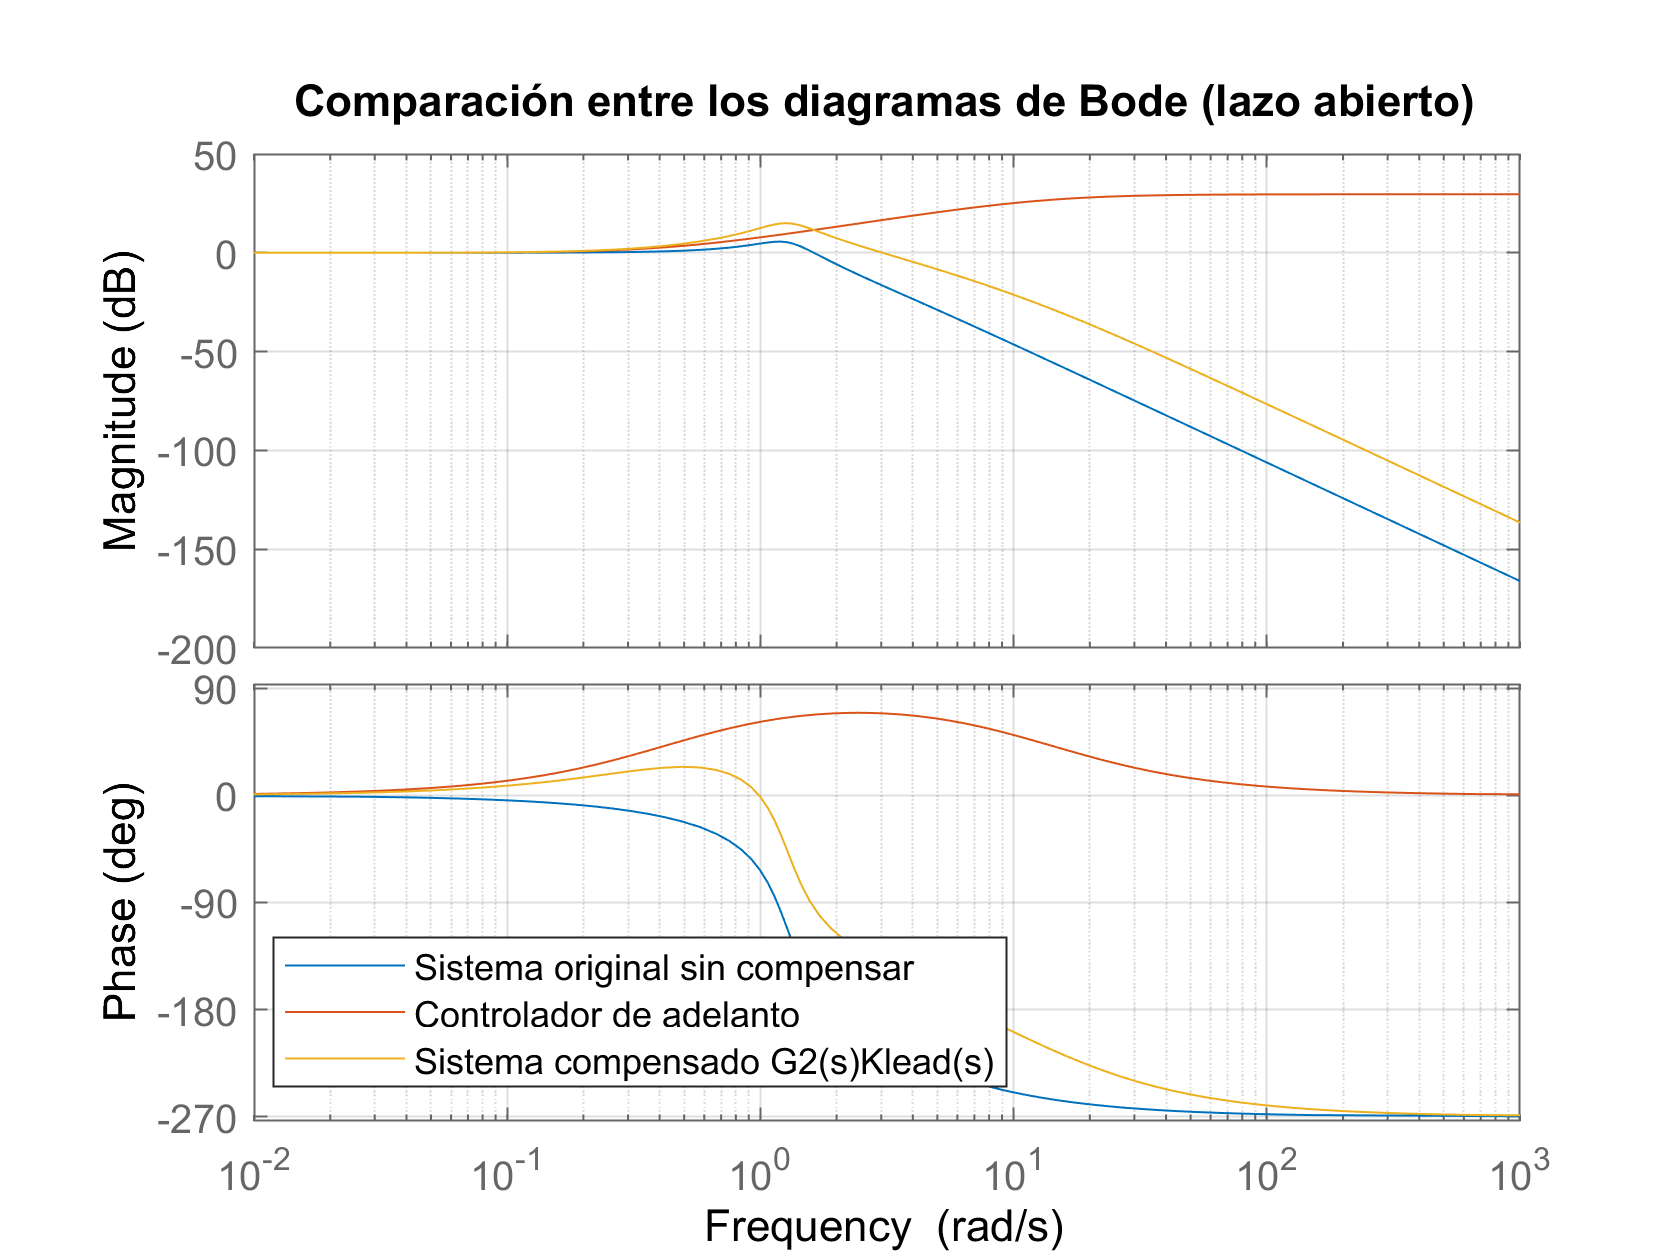

bode(G); hold on
bode(C); hold on
bode(sysC); hold on
legend('Sistema original sin compensar','Controlador de adelanto','Sistema compensado G2(s)Klead(s)','location','best');
title('Comparación entre los diagramas de Bode (lazo abierto)')
grid

## Respuestas al escalón (sistema en lazo cerrado)

hold off;

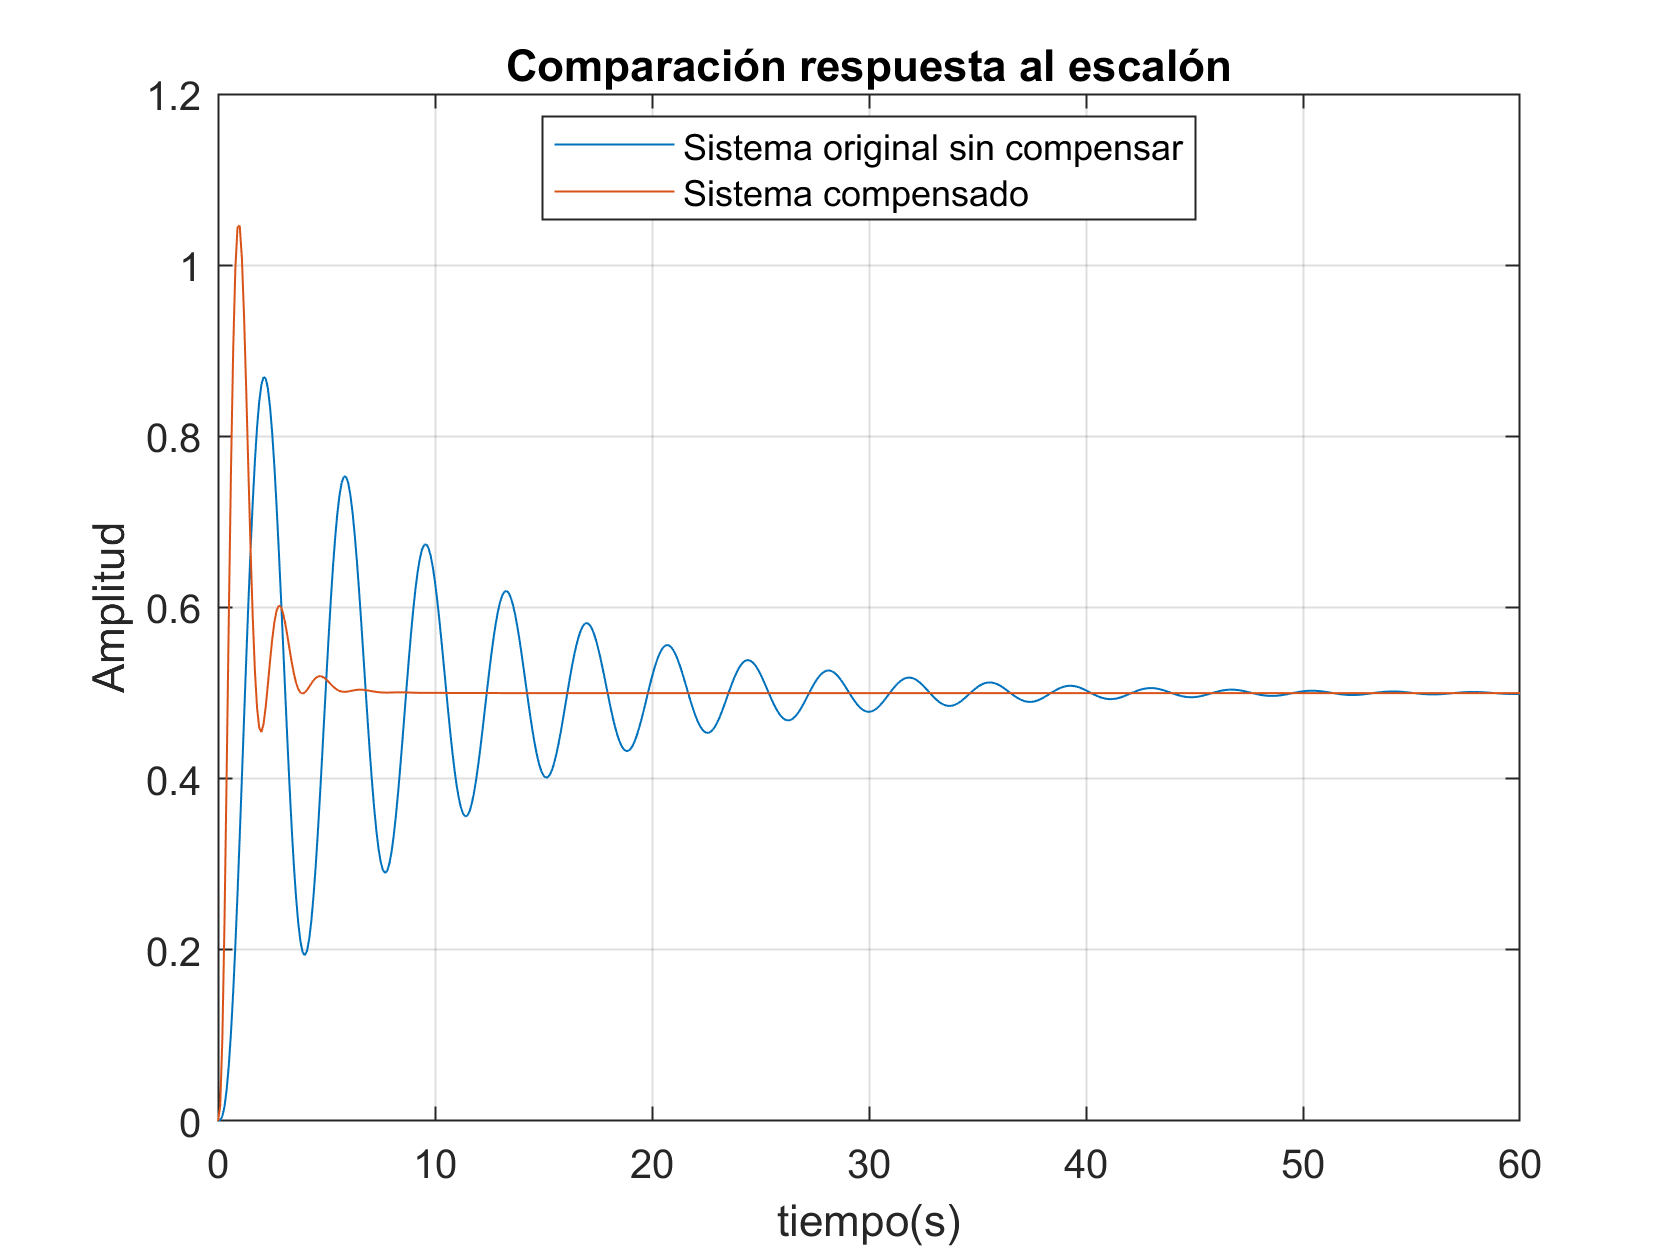

t=0:0.1:60;
fsys=feedback(G,1);
fsysC=feedback(sysC,1);
a = step(fsys,t);
b = step(fsysC,t);
plot(t,a,t,b)
legend('Sistema original sin compensar','Sistema compensado','location','best');
title('Comparación respuesta al escalón')
xlabel('tiempo(s)')
ylabel('Amplitud')
grid

## Respuestas a la rampa (sistema en lazo cerrado)

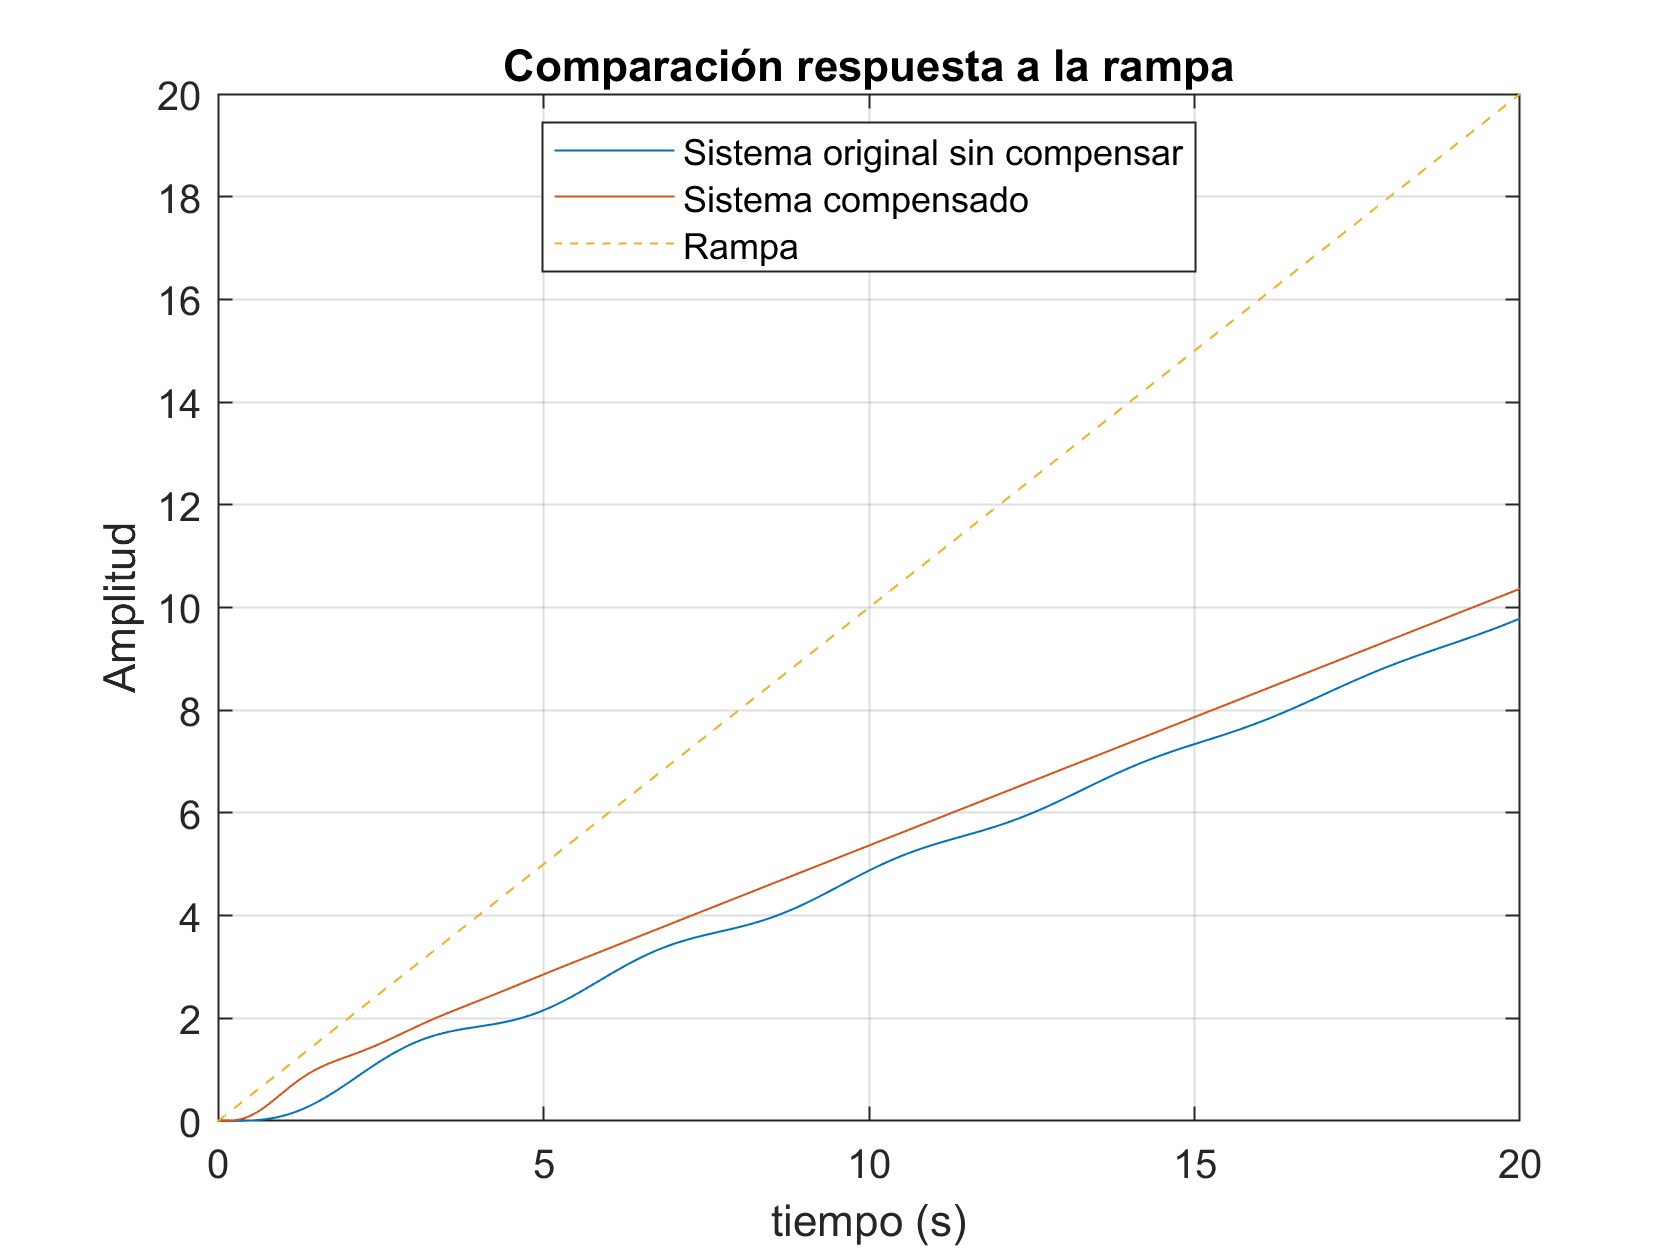

t=0:0.1:20;
r=tf(1,[1 0]);
fsys_r=r*feedback(G,1);
fsysC1_r=r*feedback(sysC,1);
a=step(fsys_r,t);
b=step(fsysC1_r,t);
plot(t,a,t,b,t,t,'--')
legend('Sistema original sin compensar','Sistema compensado','Rampa','location','best');
title('Comparación respuesta a la rampa')
xlabel('tiempo (s)')
ylabel('Amplitud')
grid